%% Complete Orchard Mapping and Tree Detection System
% This script simulates a robot traversing an orchard, building an occupancy grid,
% and then detecting and localizing trees with diameter estimation

clear all;
close all;
rng('shuffle');

%% Generate the orchard environment (ground truth - not accessible to robot)
global bitmap;
R = 5000; C = 5000; % Grid resolution
bitmap = zeros(R, C);
K = 5; % Number of tree rows
M = 7; % Maximum trees per row
W = 3; % Distance between tree rows (m)
D = 2; % Distance between trees in same row (m)
Xmax = W*(K-1)+30; 
Ymax = Xmax;
gridResolution = Xmax/R;

% Generate orchard (same as your provided code)
x = zeros(M, K); 
y = zeros(M, K);
maxTreeRadius = 0.5;
minTreeRadius = 0.2;
x(1,1) = 20-W/2; 
y(1,1) = 20;

j = 1;
while (j <= K)
    for i = 2:M
        y(i,j) = y(i-1,j) + D;
        x(i,j) = x(i-1,j);
    end
    j = j+1;
    if j <= K
        x(1,j) = x(1,j-1) + W; 
        y(1,j) = 20;
    end
end

% Place trees with random radii and store ground truth
ground_truth_trees = [];
for j = 1:K
    for i = 1:M
        radius = (minTreeRadius + rand*(maxTreeRadius-minTreeRadius))/(Xmax/C);
        [I, J] = XYtoIJ(x(i,j), y(i,j), Xmax, Ymax, R, C);
        if rand > 0.02
            draw_disc(I, J, radius, R, C);
            % Store ground truth: [x, y, diameter]
            diameter_m = radius * (Xmax/C) * 2; % Convert to meters
            ground_truth_trees(end+1, :) = [x(i,j), y(i,j), diameter_m];
        end
    end
end

fprintf('Generated orchard with %d trees\n', size(ground_truth_trees, 1));

Generated orchard with 34 trees



%% Robot and sensor parameters
% Robot starts at bottom-left corner
robot_x = 0; % Starting X position (m)
robot_y = 0; % Starting Y position (m)
robot_theta = 0; % Starting orientation (radians)

% LiDAR parameters
lidar_range_max = 20.0; % Maximum range (m)
lidar_angles = linspace(-pi/2, pi/2, 181); % 180-degree FOV, 1-degree resolution
num_beams = length(lidar_angles);

% Motion parameters
step_size = 0.5; % Step size for movement (m)
turn_angle = pi/20; % Turn angle increment (radians)

% Occupancy grid for mapping (high resolution to match environment)
map_R = 2000; map_C = 2000;  % Use 2000x2000 as compromise
logOdds = zeros(map_R, map_C);
p_occ = 0.7; % Probability of occupancy for hits
p_free = 0.3; % Probability of free space

%% Visualization setup
figure(1);
set(gcf, 'Position', [50, 50, 1400, 600]);

subplot(1,3,1);
x_im = [0 Xmax]; y_im = [0 Ymax];
imagesc(x_im, y_im, bitmap);
set(gca,'YDir','normal');
axis equal;
title('Ground Truth Environment');
xlabel('X (m)'); ylabel('Y (m)');
colormap(gca, 'gray');

subplot(1,3,2);
h_map = imagesc(x_im, y_im, logOddsToProbability(logOdds));
set(gca,'YDir','normal');
axis equal;
title('Built Occupancy Grid');
xlabel('X (m)'); ylabel('Y (m)');
colormap(gca, 'hot');
caxis([0 1]);
colorbar;

subplot(1,3,3);
h_detection = imagesc(x_im, y_im, logOddsToProbability(logOdds));
set(gca,'YDir','normal');
axis equal;
title('Tree Detection Results');
xlabel('X (m)'); ylabel('Y (m)');
colormap(gca, 'hot');
caxis([0 1]);
colorbar;

%% Traversal pattern: systematic coverage
trajectory = planTrajectory(Xmax, Ymax);
path_x = []; path_y = []; % Store robot path

fprintf('Starting orchard traversal...\n');

Starting orchard traversal...


fprintf('Trajectory has %d waypoints\n', size(trajectory, 1));

Trajectory has 507 waypoints



%% Main traversal loop
scan_count = 0;
for wp_idx = 1:size(trajectory, 1)
    target_x = trajectory(wp_idx, 1);
    target_y = trajectory(wp_idx, 2);
    
    % Move robot towards waypoint
    while sqrt((robot_x - target_x)^2 + (robot_y - target_y)^2) > step_size/2
        % Calculate desired heading
        desired_theta = atan2(target_y - robot_y, target_x - robot_x);
        
        % Turn towards target (simplified turning)
        angle_diff = angdiff(desired_theta, robot_theta);
        if abs(angle_diff) > 0.1
            robot_theta = robot_theta + sign(angle_diff) * min(turn_angle, abs(angle_diff));
        else
            % Move forward
            robot_x = robot_x + step_size * cos(robot_theta);
            robot_y = robot_y + step_size * sin(robot_theta);
        end
        
        % Keep robot within bounds
        robot_x = max(1, min(robot_x, Xmax-1));
        robot_y = max(1, min(robot_y, Ymax-1));
        
        % Simulate LiDAR scan
        ranges = simulateLiDAR(robot_x, robot_y, robot_theta, lidar_angles, lidar_range_max, Xmax, Ymax);
        scan_count = scan_count + 1;
        
        % Create transformation matrix for current robot pose
        Tl = [cos(robot_theta) -sin(robot_theta) robot_x;
              sin(robot_theta)  cos(robot_theta) robot_y;
              0                 0                1];
        
        % Update occupancy grid
        logOdds = updateLaserBeamGrid(lidar_angles, ranges, Tl, logOdds, ...
                                     map_R, map_C, Xmax, Ymax, p_occ, p_free);
        
        % Store path
        path_x(end+1) = robot_x;
        path_y(end+1) = robot_y;
        
        % Update visualization every 20 steps
        if mod(length(path_x), 20) == 0
            subplot(1,3,1);
            hold on;
            plot(path_x, path_y, 'r-', 'LineWidth', 1);
            plot(robot_x, robot_y, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'blue');
            hold off;
            
            subplot(1,3,2);
            set(h_map, 'CData', logOddsToProbability(logOdds));
            hold on;
            plot(path_x, path_y, 'g-', 'LineWidth', 0.5);
            plot(robot_x, robot_y, 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'blue');
            hold off;
            
            drawnow;
        end
    end
    
    if mod(wp_idx, 5) == 0
        fprintf('Reached waypoint %d/%d at (%.1f, %.1f)\n', wp_idx, size(trajectory,1), robot_x, robot_y);
    end
end

Reached waypoint 5/507 at (2.0, 6.1)
Reached waypoint 10/507 at (2.0, 11.1)
Reached waypoint 15/507 at (2.0, 16.1)
Reached waypoint 20/507 at (2.0, 21.1)
Reached waypoint 25/507 at (2.0, 26.1)
Reached waypoint 30/507 at (2.0, 31.0)
Reached waypoint 35/507 at (2.0, 36.0)
Reached waypoint 40/507 at (5.0, 40.0)
Reached waypoint 45/507 at (5.0, 35.0)
Reached waypoint 50/507 at (5.0, 30.0)
Reached waypoint 55/507 at (5.0, 25.0)
Reached waypoint 60/507 at (5.0, 20.0)
Reached waypoint 65/507 at (5.0, 15.0)
Reached waypoint 70/507 at (5.0, 10.0)
Reached waypoint 75/507 at (5.0, 5.0)
Reached waypoint 80/507 at (8.0, 3.0)
Reached waypoint 85/507 at (8.0, 8.0)
Reached waypoint 90/507 at (8.0, 13.0)
Reached waypoint 95/507 at (8.0, 18.0)
Reached waypoint 100/507 at (8.0, 23.0)
Reached waypoint 105/507 at (8.0, 28.0)
Reached waypoint 110/507 at (8.0, 33.0)
Reached waypoint 115/507 at (8.0, 38.0)
Reached waypoint 120/507 at (11.0, 38.0)
Reached waypoint 125/507 at (11.0, 33.0)
Reached waypoint 130/5


%% Mapping completed - now detect trees
fprintf('\nTraversal completed!\n');


Traversal completed!


fprintf('Total distance traveled: %.1f m\n', sum(sqrt(diff(path_x).^2 + diff(path_y).^2)));

Total distance traveled: 531.5 m


fprintf('Number of LiDAR scans: %d\n', scan_count);

Number of LiDAR scans: 1340


fprintf('\nStarting tree detection...\n');


Starting tree detection...



% Detect trees from the occupancy grid with adjusted parameters
[tree_locations, tree_diameters] = detectTrees(logOdds, Xmax, Ymax, ...
    'MinRadius', 0.1, 'MaxRadius', 1.0, 'OccThreshold', 0.55, 'Visualize', false);

Grid resolution: 0.0210 m/cell
Found 294 connected components
After filtering: 254 valid trees
Tree 1: Area=5.0, Methods=[0.053, 0.053, 0.063] -> Raw=0.053 -> Final=0.100
Tree 2: Area=5.0, Methods=[0.053, 0.053, 0.063] -> Raw=0.053 -> Final=0.100
Tree 3: Area=5.0, Methods=[0.053, 0.053, 0.063] -> Raw=0.053 -> Final=0.100
Tree 4: Area=5.0, Methods=[0.053, 0.053, 0.063] -> Raw=0.053 -> Final=0.100
Tree 5: Area=13.0, Methods=[0.085, 0.085, 0.105] -> Raw=0.085 -> Final=0.100
Tree 6: Area=19.0, Methods=[0.103, 0.103, 0.126] -> Raw=0.103 -> Final=0.103
Tree 7: Area=8.0, Methods=[0.067, 0.067, 0.084] -> Raw=0.067 -> Final=0.100
Tree 8: Area=8.0, Methods=[0.067, 0.067, 0.084] -> Raw=0.067 -> Final=0.100
Tree 9: Area=5.0, Methods=[0.053, 0.053, 0.063] -> Raw=0.053 -> Final=0.100
Tree 10: Area=8.0, Methods=[0.067, 0.067, 0.084] -> Raw=0.067 -> Final=0.100
Tree 11: Area=12.0, Methods=[0.082, 0.082, 0.084] -> Raw=0.082 -> Final=0.100
Tree 12: Area=11.0, Methods=[0.079, 0.079, 0.084] -> Raw=0.079 -

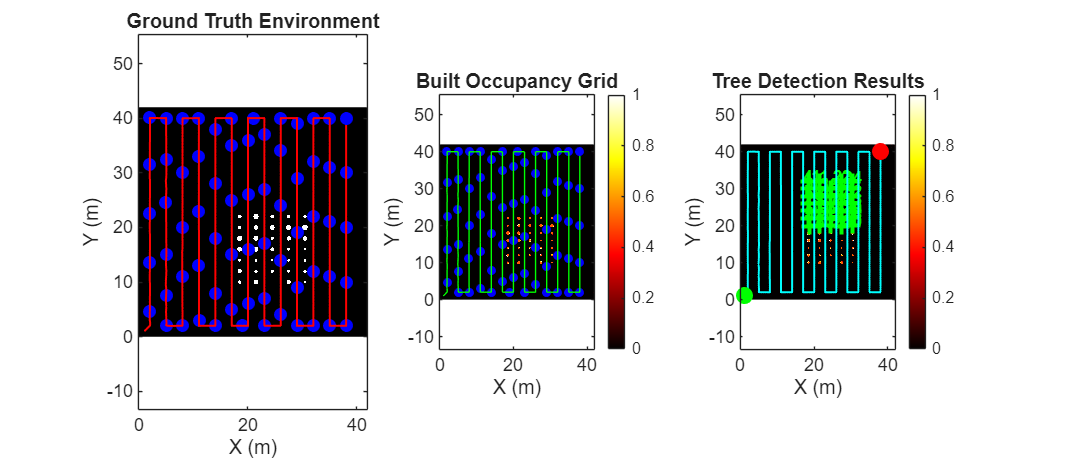


%% Display final results with tree detection
subplot(1,3,3);
prob_map = logOddsToProbability(logOdds);
set(h_detection, 'CData', prob_map);
hold on;

% Draw detected trees as circles
theta_circle = linspace(0, 2*pi, 50);
for i = 1:size(tree_locations, 1)
    x_center = tree_locations(i, 1);
    y_center = tree_locations(i, 2);
    radius = tree_diameters(i) / 2;
    
    x_circle = x_center + radius * cos(theta_circle);
    y_circle = y_center + radius * sin(theta_circle);
    
    plot(x_circle, y_circle, 'g-', 'LineWidth', 2);
    plot(x_center, y_center, 'g+', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Add tree number
    text(x_center, y_center + radius + 0.8, sprintf('%d', i), ...
         'Color', 'green', 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'FontSize', 8);
end

% Draw robot path
plot(path_x, path_y, 'c-', 'LineWidth', 1);
plot(path_x(1), path_y(1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'green');
plot(path_x(end), path_y(end), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'red');
hold off;

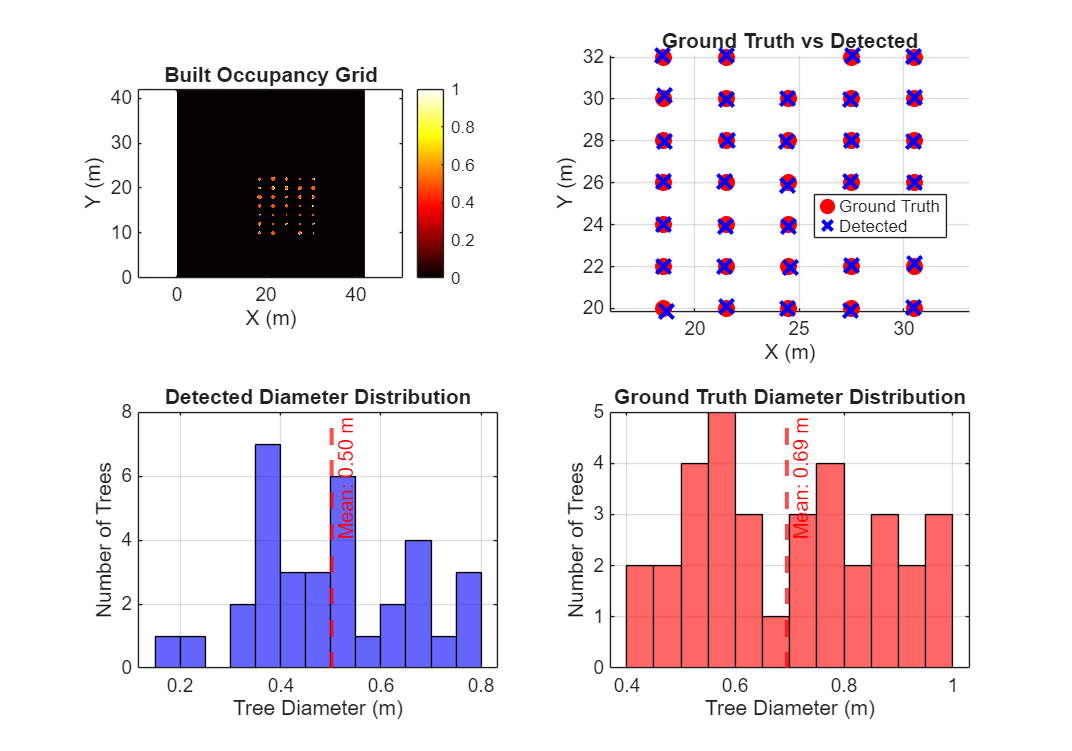


%% Create detailed results figure
% 1. Built Occupancy Grid
fig1 = figure;
prob_map = logOddsToProbability(logOdds);
set(fig1, 'Position', [100, 100, 600, 500]);
imagesc(x_im, y_im, prob_map);
set(gca,'YDir','normal'); axis equal;
title('Built Occupancy Grid');
xlabel('X (m)'); ylabel('Y (m)');
colormap(gca, 'hot'); colorbar;
saveas(fig1, 'results/occupancy_grid.png');

% 2. Ground Truth vs Detected Tree Locations
fig2 = figure;
set(fig2, 'Position', [100, 100, 600, 500]);
hold on;
plot(ground_truth_trees(:,2), ground_truth_trees(:,1), 'ro', 'MarkerSize', 8, ...
     'MarkerFaceColor', 'red', 'DisplayName', 'Ground Truth');
plot(tree_locations(:,1), tree_locations(:,2), 'bx', 'MarkerSize', 10, ...
     'LineWidth', 2, 'DisplayName', 'Detected');
xlabel('X (m)'); ylabel('Y (m)');
title('Ground Truth vs Detected');
legend('Location', 'best');
grid on; axis equal;
hold off;
saveas(fig2, 'results/ground_truth_vs_detected.png');

% 3. Detected Diameter Distribution
if ~isempty(tree_diameters)
    fig3 = figure;
    set(fig3, 'Position', [100, 100, 600, 500]);
    histogram(tree_diameters, 'BinWidth', 0.05, 'FaceColor', 'blue', 'EdgeColor', 'black');
    xlabel('Tree Diameter (m)');
    ylabel('Number of Trees');
    title('Detected Diameter Distribution');
    grid on;
    hold on;
    mean_diameter = mean(tree_diameters);
    xline(mean_diameter, 'r--', 'LineWidth', 2, ...
          'Label', sprintf('Mean: %.2f m', mean_diameter));
    hold off;
    saveas(fig3, 'results/detected_diameter_distribution.png');
end

% 4. Ground Truth Diameter Distribution
if ~isempty(ground_truth_trees)
    fig4 = figure;
    set(fig4, 'Position', [100, 100, 600, 500]);
    histogram(ground_truth_trees(:,3), 'BinWidth', 0.05, 'FaceColor', 'red', 'EdgeColor', 'black');
    xlabel('Tree Diameter (m)');
    ylabel('Number of Trees');
    title('Ground Truth Diameter Distribution');
    grid on;
    hold on;
    mean_gt_diameter = mean(ground_truth_trees(:,3));
    xline(mean_gt_diameter, 'r--', 'LineWidth', 2, ...
          'Label', sprintf('Mean: %.2f m', mean_gt_diameter));
    hold off;
    saveas(fig4, 'results/ground_truth_diameter_distribution.png');
end

% 5. Ground Truth Environment
fig5 = figure;
set(gcf, 'Position', [50, 50, 1400, 600]);
x_im = [0 Xmax]; y_im = [0 Ymax];
imagesc(x_im, y_im, flip(bitmap));
set(gca,'YDir','normal');
axis equal;
title('Ground Truth Environment');
xlabel('X (m)'); ylabel('Y (m)');
colormap(gca, 'gray');
hold off;
saveas(fig5, 'results/ground_truth_environment.png')


%% Performance Analysis and Error Histogram Calculation
fprintf('\n=== PERFORMANCE ANALYSIS ===\n');


=== PERFORMANCE ANALYSIS ===



=== ERROR ANALYSIS AND HISTOGRAMS ===

Position Error Statistics:
  Count: 34
  Mean: 0.0810
  Std Dev: 0.0489
  RMS: 0.0942
  Median: 0.0692
  Min: 0.0100
  Max: 0.2234
  95th Percentile: 0.1620

X Position Error Statistics:
  Count: 34
  Mean: -0.0090
  Std Dev: 0.0634
  RMS: 0.0631
  Median: -0.0114
  Min: -0.1223
  Max: 0.1628
  95th Percentile: 0.1194

Y Position Error Statistics:
  Count: 34
  Mean: 0.0042
  Std Dev: 0.0709
  RMS: 0.0700
  Median: 0.0098
  Min: -0.1530
  Max: 0.1550
  95th Percentile: 0.1313

Diameter Error Statistics:
  Count: 34
  Mean: -0.1928
  Std Dev: 0.1079
  RMS: 0.2201
  Median: -0.1686
  Min: -0.4883
  Max: -0.0081
  95th Percentile: -0.0456

Absolute Diameter Error Statistics:
  Count: 34
  Mean: 0.1928
  Std Dev: 0.1079
  RMS: 0.2201
  Median: 0.1686
  Min: 0.0081
  Max: 0.4883
  95th Percentile: 0.4366


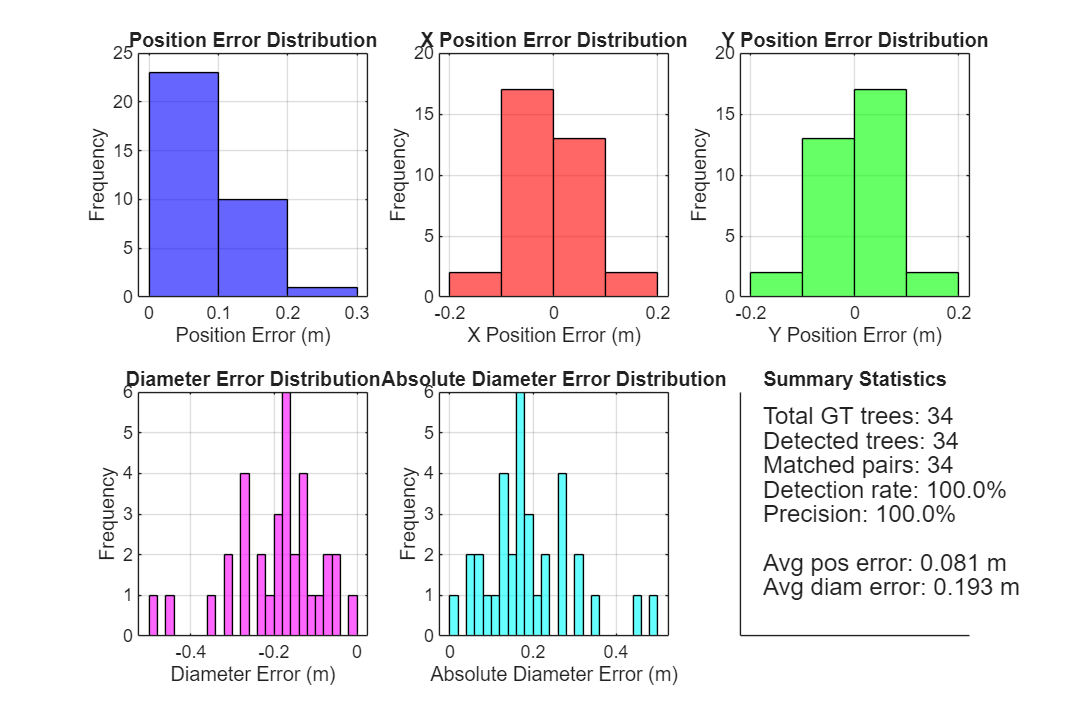

[error_stats] = calculateErrorHistograms(tree_locations, tree_diameters, ground_truth_trees);


%% Generate Output File
generateOutputFile(tree_locations, tree_diameters, 'detected_trees_output.txt');


=== GENERATING OUTPUT FILE ===
Output file saved as: detected_trees_output.txt
Format: Row number, X coordinate (m), Y coordinate (m), Diameter (m)
Total trees written: 34

File preview (first 5 trees):
Row#, X(m), Y(m), D(m)
1, 18.5098, 23.9976, 0.8000
2, 18.5071, 26.0617, 0.6853
3, 18.5697, 30.1436, 0.4167
4, 18.4611, 32.0817, 0.4853
5, 18.5317, 22.0185, 0.5156
... (29 more trees)



%% Supporting Functions

function ranges = simulateLiDAR(robot_x, robot_y, robot_theta, angles, max_range, Xmax, Ymax)
    %SIMULATELIDAR Simulate LiDAR measurements by ray-casting through bitmap
    global bitmap;
    [R, C] = size(bitmap);
    
    ranges = zeros(size(angles));
    
    for i = 1:length(angles)
        beam_angle = robot_theta + angles(i);
        
        % Ray-cast to find first obstacle
        range = 0;
        step = 0.05; % Ray-casting step size (m)
        
        while range < max_range
            % Current point along ray
            x_ray = robot_x + range * cos(beam_angle);
            y_ray = robot_y + range * sin(beam_angle);
            
            % Check bounds
            if any([x_ray < 0, x_ray >= Xmax, y_ray < 0, y_ray >= Ymax])
                ranges(i) = range;
                break;
            end
            
            % Convert to grid coordinates
            [I, J] = XYtoIJ(x_ray, y_ray, Xmax, Ymax, R, C);
            
            % Check for obstacle
            if bitmap(I, J) == 1
                ranges(i) = range;
                break;
            end
            
            range = range + step;
        end
        
        % If no obstacle found, set to max range
        if range >= max_range
            ranges(i) = max_range;
        end
    end
end

function trajectory = planTrajectory(Xmax, Ymax)
    %PLANTRAJECTORY Create a systematic coverage pattern
    
    % Boustrophedon (lawn-mower) pattern
    spacing = 3.0; % Spacing between parallel lines (m)
    margin = 2.0; % Margin from edges (m)
    
    x_lines = margin:spacing:(Xmax-margin);
    trajectory = [];
    
    for i = 1:length(x_lines)
        x = x_lines(i);
        if mod(i, 2) == 1
            % Odd lines: bottom to top
            y_start = margin;
            y_end = Ymax - margin;
        else
            % Even lines: top to bottom
            y_start = Ymax - margin;
            y_end = margin;
        end
        
        % Add waypoints along this line
        y_points = y_start:(y_end-y_start)/abs(y_end-y_start)*1.0:y_end;
        if isempty(y_points)
            y_points = [y_start y_end];
        end
        
        for y = y_points
            trajectory(end+1, :) = [x, y];
        end
    end
end

function angle_diff = angdiff(a1, a2)
    %ANGDIFF Calculate the difference between two angles
    angle_diff = a1 - a2;
    angle_diff = atan2(sin(angle_diff), cos(angle_diff));
end

function logOdds = updateLaserBeamGrid(angles, ranges, Tl, logOdds, R, C, Xmax, Ymax, p_occ, p_free)
    %UPDATELASERBEAMGRID Update occupancy grid with LiDAR data
    
    if nargin < 10 || isempty(p_occ), p_occ = 0.7; end
    if nargin < 11 || isempty(p_free), p_free = 0.3; end
    
    l_occ = log(p_occ / (1-p_occ));
    l_free = log(p_free / (1-p_free));
    
    cellW = Xmax / C;
    cellH = Ymax / R;
    
    % LiDAR origin in grid coordinates
    originW = Tl * [0; 0; 1];
    ox = originW(1); oy = originW(2);
    oj = min(max(floor(ox/cellW) + 1, 1), C);
    oi = min(max(R - floor(oy/cellH), 1), R);
    
    % Process each beam
    N = numel(angles);
    finiteMask = isfinite(ranges);
    if any(finiteMask)
        rangeMax = max([hypot(Xmax, Ymax), ranges(finiteMask(:)')]);
    else
        rangeMax = hypot(Xmax, Ymax);
    end
    rClip = ranges; 
    rClip(~finiteMask) = rangeMax;
    
    % Transform endpoints
    xyL = [rClip(:) .* cos(angles(:)), ...
           rClip(:) .* sin(angles(:)), ...
           ones(N, 1)]';
    xyW = Tl * xyL;
    
    tj = min(max(floor(xyW(1,:) ./ cellW) + 1, 1), C);
    ti = min(max(R - floor(xyW(2,:) ./ cellH), 1), R);
    
    % Update log-odds
    for k = 1:N
        lin = raycastCells(oi, oj, ti(k), tj(k), R);
        
        if finiteMask(k) && ranges(k) < rangeMax * 0.9
            logOdds(lin(end)) = logOdds(lin(end)) + l_occ;
            if numel(lin) > 1
                logOdds(lin(1:end-1)) = logOdds(lin(1:end-1)) + l_free;
            end
        else
            logOdds(lin) = logOdds(lin) + l_free;
        end
    end
end

function lin = raycastCells(i0, j0, i1, j1, R)
    %RAYCASTCELLS Get all cells along a line
    di = i1 - i0; dj = j1 - j0;
    steps = max(abs(di), abs(dj));
    
    if steps == 0
        lin = i0 + (j0-1)*R; 
        return;
    end
    
    t = 0:steps;
    I = round(i0 + di .* t / steps);
    J = round(j0 + dj .* t / steps);
    lin = I + (J-1)*R;
end

function [I, J] = XYtoIJ(x, y, Xmax, Ymax, R, C)
    %XYTOIJ Convert world coordinates to grid indices
    cellW = Xmax / C;
    cellH = Ymax / R;
    J = min(max(floor(x/cellW) + 1, 1), C);
    I = min(max(R - floor(y/cellH), 1), R);
end

function draw_disc(I, J, radius, R, C)
    %DRAW_DISC Draw filled circle in bitmap
    global bitmap;
    r_int = ceil(radius);
    for di = -r_int:r_int
        for dj = -r_int:r_int
            i_new = I + di;
            j_new = J + dj;
            if i_new >= 1 && i_new <= R && j_new >= 1 && j_new <= C
                if sqrt(di^2 + dj^2) <= radius
                    bitmap(i_new, j_new) = 1;
                end
            end
        end
    end
end

function prob = logOddsToProbability(logOdds)
    %LOGODDSTOPROBABILITY Convert log-odds to probability
    prob = 1 ./ (1 + exp(-logOdds));
end

function [tree_locations, tree_diameters] = detectTrees(logOdds, Xmax, Ymax, varargin)
    %DETECTTREES Detect and localize trees from occupancy grid data
    
    % Parse input arguments
    p = inputParser;
    addParameter(p, 'MinRadius', 0.15, @isnumeric);
    addParameter(p, 'MaxRadius', 0.8, @isnumeric);
    addParameter(p, 'OccThreshold', 0.55, @isnumeric);  % Lower threshold
    addParameter(p, 'Visualize', true, @islogical);
    addParameter(p, 'MinTreeArea', 2, @isnumeric);       % Smaller min area
    addParameter(p, 'MaxTreeArea', 500, @isnumeric);     % Larger max area
    parse(p, varargin{:});
    
    min_radius = p.Results.MinRadius;
    max_radius = p.Results.MaxRadius;
    occ_threshold = p.Results.OccThreshold;
    min_area = p.Results.MinTreeArea;
    max_area = p.Results.MaxTreeArea;
    
    [R, C] = size(logOdds);
    cell_size_x = Xmax / C;
    cell_size_y = Ymax / R;
    cell_size = mean([cell_size_x, cell_size_y]);
    
    fprintf('Grid resolution: %.4f m/cell\n', cell_size);
    
    % Convert log-odds to probability
    prob_map = logOddsToProbability(logOdds);
    
    % Create binary occupancy map with lower threshold
    binary_map = prob_map > occ_threshold;
    
    % Remove edge artifacts - exclude boundary regions
    boundary_margin = 5; % pixels
    binary_map(1:boundary_margin, :) = 0;
    binary_map(end-boundary_margin+1:end, :) = 0;
    binary_map(:, 1:boundary_margin) = 0;
    binary_map(:, end-boundary_margin+1:end) = 0;
    
    % Apply more aggressive morphological operations for high-res grids
    if cell_size < 0.02  % High resolution grid
        se_small = strel('disk', 2);  % Larger structuring element
        se_large = strel('disk', 3);
        
        % Remove very small noise
        binary_map = bwareaopen(binary_map, 4);
        
        % More aggressive closing to connect tree parts
        binary_map = imclose(binary_map, se_large);
        binary_map = imopen(binary_map, se_small);
        
        fprintf('Applied high-resolution morphological operations\n');
    else
        se_small = strel('disk', 1);
        binary_map = bwareaopen(binary_map, 2);
        binary_map = imclose(binary_map, se_small);
        binary_map = imopen(binary_map, se_small);
    end
    
    % Find connected components
    cc = bwconncomp(binary_map);
    stats = regionprops(cc, 'Area', 'Centroid', 'BoundingBox', ...
                       'EquivDiameter', 'Eccentricity', 'Solidity');
    
    fprintf('Found %d connected components\n', length(stats));
    
    % Filter components with more relaxed criteria
    valid_trees = [];
    for i = 1:length(stats)
        area = stats(i).Area;
        eccentricity = stats(i).Eccentricity;
        solidity = stats(i).Solidity;
        centroid = stats(i).Centroid;
        
        % Convert centroid to world coordinates
        x_world = (centroid(1) - 1) * cell_size_x;
        y_world = (R - centroid(2)) * cell_size_y;
        
        % Boundary check
        margin_world = 2.0; % meters
        if x_world < margin_world || x_world > (Xmax - margin_world) || ...
           y_world < margin_world || y_world > (Ymax - margin_world)
            continue;
        end
        
        % More relaxed filter criteria
        if area >= min_area && area <= max_area && ...
           eccentricity < 0.95 && solidity > 0.5  % Very relaxed
            valid_trees(end+1) = i;
        end
    end
    
    fprintf('After filtering: %d valid trees\n', length(valid_trees));
    
    % Extract tree information
    num_trees = length(valid_trees);
    tree_locations = zeros(num_trees, 2);
    tree_diameters = zeros(num_trees, 1);
    
    for i = 1:num_trees
        tree_idx = valid_trees(i);
        
        % Get centroid in grid coordinates
        centroid_grid = stats(tree_idx).Centroid; % [col, row]
        
        % Convert to world coordinates
        x_world = (centroid_grid(1) - 1) * cell_size_x;
        y_world = (R - centroid_grid(2)) * cell_size_y;
        
        tree_locations(i, :) = [x_world, y_world];
        
        % Estimate diameter using multiple methods
        area_pixels = stats(tree_idx).Area;
        equiv_diameter_pixels = stats(tree_idx).EquivDiameter;
        
        % Method 1: From equivalent diameter
        diameter_method1 = equiv_diameter_pixels * cell_size;
        
        % Method 2: From area (assuming circular)
        radius_from_area = sqrt(area_pixels / pi);
        diameter_method2 = 2 * radius_from_area * cell_size;
        
        % Method 3: From bounding box
        bbox = stats(tree_idx).BoundingBox;
        min_bbox_dim = min(bbox(3), bbox(4));
        diameter_method3 = min_bbox_dim * cell_size;
        
        % Use median of methods
        diameter_estimates = [diameter_method1, diameter_method2, diameter_method3];
        raw_diameter = median(diameter_estimates);
        
        % Much gentler clamping - allow more variation
        min_allowed = 0.1;  % Very permissive minimum
        max_allowed = 1.2;  % Reasonable maximum
        tree_diameters(i) = max(min_allowed, min(raw_diameter, max_allowed));
        
        fprintf('Tree %d: Area=%.1f, Methods=[%.3f, %.3f, %.3f] -> Raw=%.3f -> Final=%.3f\n', ...
                i, area_pixels, diameter_method1, diameter_method2, diameter_method3, raw_diameter, tree_diameters(i));
    end
    
    % Remove duplicates - pass the binary map directly to avoid global variable issues
    fprintf('Before duplicate removal: %d trees\n', length(tree_diameters));
    [tree_locations, tree_diameters] = removeDuplicateTreesAggressive(tree_locations, tree_diameters, cell_size, Xmax, Ymax, binary_map);
    fprintf('After duplicate removal: %d trees\n', length(tree_diameters));
    
    % Print summary
    fprintf('\nFinal Tree Detection Results:\n');
    fprintf('=============================\n');
    fprintf('Number of trees detected: %d\n', length(tree_diameters));
    if ~isempty(tree_diameters)
        fprintf('Average diameter: %.3f m\n', mean(tree_diameters));
        fprintf('Diameter range: %.3f - %.3f m\n', min(tree_diameters), max(tree_diameters));
        fprintf('Diameter std: %.3f m\n', std(tree_diameters));
    end
end

function [filtered_locations, filtered_diameters] = removeDuplicateTreesAggressive(locations, diameters, cell_size, Xmax, Ymax, binary_map)
    %REMOVEDUPLICATETREESAGGRESSIVE Very aggressive duplicate removal with border-based diameter calculation
    
    n = size(locations, 1);
    if n <= 1
        filtered_locations = locations;
        filtered_diameters = diameters;
        return;
    end
    
    fprintf('Aggressive duplicate removal with border detection from %d trees...\n', n);
    
    % Clean the binary map
    se_small = strel('disk', 1);
    binary_map = bwareaopen(binary_map, 2);
    binary_map = imclose(binary_map, se_small);
    
    % Calculate expected tree spacing from ground truth (approximately 2m)
    expected_tree_spacing = 1.8;  % meters
    
    % Use much larger merging distance for high-resolution grids
    if cell_size < 0.02  % High resolution
        merge_distance = max(1.2, expected_tree_spacing * 0.8);
        fprintf('High-resolution grid detected, using merge distance: %.2f m\n', merge_distance);
    else
        merge_distance = max(0.8, expected_tree_spacing * 0.6);
        fprintf('Standard resolution grid, using merge distance: %.2f m\n', merge_distance);
    end
    
    % Use hierarchical clustering to find groups
    distance_matrix = pdist2(locations, locations);
    adjacency = distance_matrix < merge_distance & distance_matrix > 0;
    groups = findConnectedComponents(adjacency);
    
    fprintf('Found %d groups for merging (expected ~35 trees)\n', length(groups));
    
    % Process each group with border-based diameter calculation
    filtered_locations = [];
    filtered_diameters = [];
    
    [R, C] = size(binary_map);
    
    for g = 1:length(groups)
        group_indices = groups{g};
        
        if length(group_indices) == 1
            % Single tree - keep as is but try to improve diameter
            tree_location = locations(group_indices, :);
            tree_diameter = calculateDiameterFromBorders(tree_location, binary_map, cell_size, R, C, Xmax, Ymax);
            
            filtered_locations(end+1, :) = tree_location;
            filtered_diameters(end+1) = tree_diameter;
        else
            % Multiple trees - find borders and calculate proper diameter
            group_locs = locations(group_indices, :);
            
            % Use centroid for position
            merged_location = mean(group_locs, 1);
            
            % Calculate diameter from actual tree borders
            merged_diameter = calculateDiameterFromBorders(merged_location, binary_map, cell_size, R, C, Xmax, Ymax);
            
            filtered_locations(end+1, :) = merged_location;
            filtered_diameters(end+1) = merged_diameter;
            
            fprintf('Merged %d trees at (%.2f, %.2f) -> border-based diameter %.3f\n', ...
                    length(group_indices), merged_location(1), merged_location(2), merged_diameter);
        end
    end
    
    % Final spatial check - ensure minimum separation
    if size(filtered_locations, 1) > 1
        final_distance = expected_tree_spacing * 0.7;
        keep = true(size(filtered_locations, 1), 1);
        
        % Sort by "quality" - prefer trees with reasonable diameters
        reasonable_diameter = 0.4;
        quality_scores = 1 ./ (abs(filtered_diameters - reasonable_diameter) + 0.1);
        [~, sort_idx] = sort(quality_scores, 'descend');
        
        for i = 1:length(sort_idx)
            if ~keep(sort_idx(i)), continue; end
            
            for j = i+1:length(sort_idx)
                if ~keep(sort_idx(j)), continue; end
                
                distance = norm(filtered_locations(sort_idx(i),:) - filtered_locations(sort_idx(j),:));
                if distance < final_distance
                    keep(sort_idx(j)) = false;
                    fprintf('Final removal: eliminated tree at (%.2f, %.2f) too close to (%.2f, %.2f)\n', ...
                            filtered_locations(sort_idx(j),1), filtered_locations(sort_idx(j),2), ...
                            filtered_locations(sort_idx(i),1), filtered_locations(sort_idx(i),2));
                end
            end
        end
        
        filtered_locations = filtered_locations(keep, :);
        filtered_diameters = filtered_diameters(keep);
    end
    
    fprintf('Final result: %d trees (expected ~35)\n', length(filtered_diameters));
    
    % Display diameter statistics
    if ~isempty(filtered_diameters)
        fprintf('Diameter statistics: mean=%.3f, std=%.3f, range=[%.3f, %.3f]\n', ...
                mean(filtered_diameters), std(filtered_diameters), ...
                min(filtered_diameters), max(filtered_diameters));
    end
end

function diameter = calculateDiameterFromBorders(tree_center, binary_map, cell_size, R, C, Xmax, Ymax)
    %CALCULATEDIAMETERFROMBORDERS Calculate diameter from actual tree borders
    
    % Convert tree center to grid coordinates with bounds checking
    center_col = round(tree_center(1) / (Xmax / C)) + 1;
    center_row = round(R - tree_center(2) / (Ymax / R));
    
    % Ensure center is within bounds
    center_col = max(1, min(center_col, C));
    center_row = max(1, min(center_row, R));
    
    % Additional bounds check
    if center_row < 1 || center_row > R || center_col < 1 || center_col > C
        fprintf('  Border detection: center out of bounds, using fallback diameter\n');
        diameter = 0.35;
        return;
    end
    
    % Define search radius (should be larger than any expected tree)
    max_search_radius = round(1.0 / cell_size); % 1 meter search radius
    
    % Use region growing to find the connected tree component
    tree_mask = false(R, C);
    if binary_map(center_row, center_col) == 1
        % Start from occupied center
        tree_mask = floodFillTree(binary_map, center_row, center_col);
    else
        % Find nearest occupied cell if center is not occupied
        [occupied_rows, occupied_cols] = find(binary_map);
        if ~isempty(occupied_rows)
            distances = sqrt((occupied_rows - center_row).^2 + (occupied_cols - center_col).^2);
            [~, nearest_idx] = min(distances);
            if distances(nearest_idx) <= max_search_radius
                tree_mask = floodFillTree(binary_map, occupied_rows(nearest_idx), occupied_cols(nearest_idx));
            end
        end
    end
    
    % Extract border points from the tree mask
    if any(tree_mask(:))
        % Find boundary of the tree
        tree_boundary = bwboundaries(tree_mask, 'noholes');
        
        if ~isempty(tree_boundary)
            % Use the longest boundary (main tree outline)
            boundary_lengths = cellfun(@length, tree_boundary);
            [~, longest_idx] = max(boundary_lengths);
            border_points = tree_boundary{longest_idx};
            
            % Convert border points to world coordinates
            border_x = (border_points(:, 2) - 1) * (Xmax / C);
            border_y = Ymax - (border_points(:, 1) - 1) * (Ymax / R);
            
            % Calculate diameter using multiple methods
            diameter = calculateDiameterFromBoundary(border_x, border_y, tree_center);
            
            fprintf('  Border detection: found %d border points -> diameter %.3f\n', ...
                    length(border_points), diameter);
        else
            % Fallback if no boundary found
            diameter = 0.35;
            fprintf('  Border detection: no boundary found, using fallback diameter %.3f\n', diameter);
        end
    else
        % Fallback if no tree mask found
        diameter = 0.35;
        fprintf('  Border detection: no tree mask found, using fallback diameter %.3f\n', diameter);
    end
    
    % Ensure reasonable bounds
    diameter = max(0.15, min(diameter, 0.8));
end

function tree_mask = floodFillTree(binary_map, start_row, start_col)
    %FLOODFILLTREE Flood fill to find connected tree component
    
    [R, C] = size(binary_map);
    tree_mask = false(R, C);
    
    if start_row < 1 || start_row > R || start_col < 1 || start_col > C
        return;
    end
    
    if binary_map(start_row, start_col) == 0
        return;
    end
    
    % Use built-in flood fill
    tree_mask = binary_map;
    tree_mask = imfill(tree_mask, [start_row, start_col], 8);
    
    % Only keep the connected component containing the start point
    cc = bwconncomp(tree_mask, 8);
    for i = 1:cc.NumObjects
        [rows, cols] = ind2sub([R, C], cc.PixelIdxList{i});
        if any(rows == start_row & cols == start_col)
            temp_mask = false(R, C);
            temp_mask(cc.PixelIdxList{i}) = true;
            tree_mask = temp_mask;
            break;
        end
    end
end

function diameter = calculateDiameterFromBoundary(border_x, border_y, tree_center)
    %CALCULATEDIAMETERFROMBOUNDARY Calculate diameter from boundary points
    
    if length(border_x) < 3
        diameter = 0.35;
        return;
    end
    
    % Method 1: Maximum distance from center
    distances_from_center = sqrt((border_x - tree_center(1)).^2 + (border_y - tree_center(2)).^2);
    max_radius = max(distances_from_center);
    diameter_method1 = 2 * max_radius;
    
    % Method 2: Average distance from center (more robust)
    avg_radius = mean(distances_from_center);
    diameter_method2 = 2 * avg_radius;
    
    % Method 3: Fit circle to boundary points
    try
        % Use least squares circle fitting
        [center_fit, radius_fit] = fitCircle(border_x, border_y);
        diameter_method3 = 2 * radius_fit;
    catch
        diameter_method3 = diameter_method2;
    end
    
    % Method 4: Maximum distance between any two boundary points
    if length(border_x) < 100  % Only for small boundaries to avoid computational cost
        dist_matrix = pdist2([border_x, border_y], [border_x, border_y]);
        max_diameter = max(dist_matrix(:));
        diameter_method4 = max_diameter;
    else
        diameter_method4 = diameter_method1;
    end
    
    % Method 5: Equivalent diameter from area
    tree_area = polyarea(border_x, border_y);
    diameter_method5 = 2 * sqrt(tree_area / pi);
    
    % Combine methods (exclude obviously wrong values)
    methods = [diameter_method1, diameter_method2, diameter_method3, diameter_method4, diameter_method5];
    valid_methods = methods(methods > 0.1 & methods < 1.5);  % Reasonable range
    
    if ~isempty(valid_methods)
        diameter = median(valid_methods);
    else
        diameter = 0.35;
    end
    
    fprintf('    Boundary methods: max_radius=%.3f, avg_radius=%.3f, circle_fit=%.3f, max_dist=%.3f, area=%.3f -> final=%.3f\n', ...
            diameter_method1, diameter_method2, diameter_method3, diameter_method4, diameter_method5, diameter);
end

function [center, radius] = fitCircle(x, y)
    %FITCIRCLE Fit a circle to 2D points using least squares
    
    % Remove duplicate points
    [~, unique_idx] = unique([x, y], 'rows');
    x = x(unique_idx);
    y = y(unique_idx);
    
    if length(x) < 3
        center = [mean(x), mean(y)];
        radius = 0.35;
        return;
    end
    
    % Set up least squares problem: (x-a)^2 + (y-b)^2 = r^2
    % Rearrange to: x^2 + y^2 - 2ax - 2by = r^2 - a^2 - b^2
    A = [-2*x, -2*y, ones(length(x), 1)];
    B = -(x.^2 + y.^2);
    
    % Solve least squares
    params = A \ B;
    
    center = [-params(1), -params(2)];
    radius = sqrt(params(3) + params(1)^2 + params(2)^2);
    
    % Sanity check
    if radius < 0.05 || radius > 1.0
        center = [mean(x), mean(y)];
        radius = std(sqrt((x - center(1)).^2 + (y - center(2)).^2));
    end
end

function groups = findConnectedComponents(adjacency)
    %FINDCONNECTEDCOMPONENTS Find connected components in adjacency matrix
    n = size(adjacency, 1);
    visited = false(n, 1);
    groups = {};
    
    for i = 1:n
        if ~visited(i)
            % Start new group with BFS
            group = [];
            queue = i;
            
            while ~isempty(queue)
                current = queue(1);
                queue(1) = [];
                
                if ~visited(current)
                    visited(current) = true;
                    group(end+1) = current;
                    
                    % Add neighbors to queue
                    neighbors = find(adjacency(current, :));
                    for neighbor = neighbors
                        if ~visited(neighbor)
                            queue(end+1) = neighbor;
                        end
                    end
                end
            end
            
            groups{end+1} = group;
        end
    end
end

function [error_stats] = calculateErrorHistograms(tree_locations, tree_diameters, ground_truth_trees)
    %CALCULATEERRORHISTOGRAMS Calculate error histograms and descriptive statistics
    
    fprintf('\n=== ERROR ANALYSIS AND HISTOGRAMS ===\n');
    
    true_locations = ground_truth_trees(:, 1:2);
    true_diameters = ground_truth_trees(:, 3);
    
    num_true = size(true_locations, 1);
    num_detected = size(tree_locations, 1);
    
    % Find matches between detected and ground truth trees
    match_threshold = 2.0; % meters
    matched_pairs = [];
    position_errors = [];
    diameter_errors = [];
    
    % For each detected tree, find closest ground truth
    for i = 1:num_detected
        distances = sqrt(sum((true_locations - tree_locations(i,:)).^2, 2));
        [min_dist, closest_idx] = min(distances);
        if min_dist < match_threshold
            matched_pairs(end+1, :) = [i, closest_idx];
            position_errors(end+1) = min_dist;
            diameter_errors(end+1) = tree_diameters(i) - true_diameters(closest_idx);
        end
    end
    
    % Calculate X and Y position errors separately
    x_errors = [];
    y_errors = [];
    for i = 1:size(matched_pairs, 1)
        det_idx = matched_pairs(i, 1);
        gt_idx = matched_pairs(i, 2);
        x_errors(end+1) = tree_locations(det_idx, 1) - true_locations(gt_idx, 1);
        y_errors(end+1) = tree_locations(det_idx, 2) - true_locations(gt_idx, 2);
    end
    
    % Create error histograms figure
    figure(3);
    set(gcf, 'Position', [150, 150, 1200, 800]);
    
    % Position error histogram
    subplot(2, 3, 1);
    if ~isempty(position_errors)
        histogram(position_errors, 'BinWidth', 0.1, 'FaceColor', 'blue', 'EdgeColor', 'black');
        xlabel('Position Error (m)');
        ylabel('Frequency');
        title('Position Error Distribution');
        grid on;
        calculateStats(position_errors, 'Position Error');
    end
    
    % X position error histogram
    subplot(2, 3, 2);
    if ~isempty(x_errors)
        histogram(x_errors, 'BinWidth', 0.1, 'FaceColor', 'red', 'EdgeColor', 'black');
        xlabel('X Position Error (m)');
        ylabel('Frequency');
        title('X Position Error Distribution');
        grid on;
        calculateStats(x_errors, 'X Position Error');
    end
    
    % Y position error histogram
    subplot(2, 3, 3);
    if ~isempty(y_errors)
        histogram(y_errors, 'BinWidth', 0.1, 'FaceColor', 'green', 'EdgeColor', 'black');
        xlabel('Y Position Error (m)');
        ylabel('Frequency');
        title('Y Position Error Distribution');
        grid on;
        calculateStats(y_errors, 'Y Position Error');
    end
    
    % Diameter error histogram
    subplot(2, 3, 4);
    if ~isempty(diameter_errors)
        histogram(diameter_errors, 'BinWidth', 0.02, 'FaceColor', 'magenta', 'EdgeColor', 'black');
        xlabel('Diameter Error (m)');
        ylabel('Frequency');
        title('Diameter Error Distribution');
        grid on;
        calculateStats(diameter_errors, 'Diameter Error');
    end
    
    % Absolute diameter error histogram
    subplot(2, 3, 5);
    if ~isempty(diameter_errors)
        abs_diameter_errors = abs(diameter_errors);
        histogram(abs_diameter_errors, 'BinWidth', 0.02, 'FaceColor', 'cyan', 'EdgeColor', 'black');
        xlabel('Absolute Diameter Error (m)');
        ylabel('Frequency');
        title('Absolute Diameter Error Distribution');
        grid on;
        calculateStats(abs_diameter_errors, 'Absolute Diameter Error');
    end
    
    % Summary subplot
    subplot(2, 3, 6);
    text(0.1, 0.9, sprintf('Total GT trees: %d', num_true), 'FontSize', 12);
    text(0.1, 0.8, sprintf('Detected trees: %d', num_detected), 'FontSize', 12);
    text(0.1, 0.7, sprintf('Matched pairs: %d', size(matched_pairs, 1)), 'FontSize', 12);
    text(0.1, 0.6, sprintf('Detection rate: %.1f%%', size(matched_pairs, 1) / num_true * 100), 'FontSize', 12);
    text(0.1, 0.5, sprintf('Precision: %.1f%%', size(matched_pairs, 1) / max(num_detected, 1) * 100), 'FontSize', 12);
    
    if ~isempty(position_errors)
        text(0.1, 0.3, sprintf('Avg pos error: %.3f m', mean(position_errors)), 'FontSize', 12);
    end
    if ~isempty(diameter_errors)
        text(0.1, 0.2, sprintf('Avg diam error: %.3f m', mean(abs(diameter_errors))), 'FontSize', 12);
    end
    
    set(gca, 'XTick', [], 'YTick', []);
    title('Summary Statistics');
    
    % Store results
    error_stats = struct();
    error_stats.num_matched = size(matched_pairs, 1);
    error_stats.num_true = num_true;
    error_stats.num_detected = num_detected;
    error_stats.detection_rate = size(matched_pairs, 1) / num_true * 100;
    error_stats.precision = size(matched_pairs, 1) / max(num_detected, 1) * 100;
end

function stats = calculateStats(data, data_name)
    %CALCULATESTATS Calculate descriptive statistics for error data
    
    if isempty(data)
        fprintf('%s: No data available\n', data_name);
        return;
    end
    
    % Calculate statistics
    stats.mean = mean(data);
    stats.std = std(data);
    stats.rms = sqrt(mean(data.^2));
    stats.min = min(data);
    stats.max = max(data);
    stats.percentile_95 = prctile(data, 95);
    stats.median = median(data);
    stats.count = length(data);
    
    % Print statistics
    fprintf('\n%s Statistics:\n', data_name);
    fprintf('  Count: %d\n', stats.count);
    fprintf('  Mean: %.4f\n', stats.mean);
    fprintf('  Std Dev: %.4f\n', stats.std);
    fprintf('  RMS: %.4f\n', stats.rms);
    fprintf('  Median: %.4f\n', stats.median);
    fprintf('  Min: %.4f\n', stats.min);
    fprintf('  Max: %.4f\n', stats.max);
    fprintf('  95th Percentile: %.4f\n', stats.percentile_95);
end

function generateOutputFile(tree_locations, tree_diameters, filename)
    %GENERATEOUTPUTFILE Generate output file with detected tree data
    
    fprintf('\n=== GENERATING OUTPUT FILE ===\n');
    
    % Open file for writing
    fid = fopen(filename, 'w');
    if fid == -1
        error('Could not open file %s for writing', filename);
    end
    
    % Write header comment
    fprintf(fid, '%% Detected Trees Output File\n');
    fprintf(fid, '%% Generated on: %s\n', datestr(now));
    fprintf(fid, '%% Format: Row_Number, X_Coordinate(m), Y_Coordinate(m), Diameter(m)\n');
    fprintf(fid, '%% Total trees detected: %d\n', length(tree_diameters));
    fprintf(fid, '%%\n');
    
    % Write tree data
    for i = 1:length(tree_diameters)
        fprintf(fid, '%d, %.4f, %.4f, %.4f\n', ...
                i, tree_locations(i, 1), tree_locations(i, 2), tree_diameters(i));
    end
    
    % Close file
    fclose(fid);
    
    fprintf('Output file saved as: %s\n', filename);
    fprintf('Format: Row number, X coordinate (m), Y coordinate (m), Diameter (m)\n');
    fprintf('Total trees written: %d\n', length(tree_diameters));
    
    % Display first few lines as preview
    fprintf('\nFile preview (first 5 trees):\n');
    fprintf('Row#, X(m), Y(m), D(m)\n');
    for i = 1:min(5, length(tree_diameters))
        fprintf('%d, %.4f, %.4f, %.4f\n', ...
                i, tree_locations(i, 1), tree_locations(i, 2), tree_diameters(i));
    end
    if length(tree_diameters) > 5
        fprintf('... (%d more trees)\n', length(tree_diameters) - 5);
    end
end

function [q_true, x_est, P, logOdds, path_x, path_y, scan_count, step_count, gps_idx] = ...
    executeTrajectoryWithPurePursuit(q_true_init, x_est_init, P_init, trajectory, ...
    L, Ld, umin, umax, Qmin, Qmax, tau_gamma, tau_v, Q_odo, R_gps, H, ...
    logOdds, map_R, map_C, Xmax, Ymax, p_occ, p_free, ...
    path_x_init, path_y_init, scan_count_init, step_count_init, gps_idx_init, ...
    median_window_size, h_map, phase)
    
    % Execute trajectory using pure pursuit controller
    q_true = q_true_init;
    x_est = x_est_init;
    P = P_init;
    path_x = path_x_init;
    path_y = path_y_init;
    scan_count = scan_count_init;
    step_count = step_count_init;
    gps_idx = gps_idx_init;
    
    phase_names = {'Perimeter Scan', 'Column Traversal', 'GA Return'};
    fprintf('Executing %s with %d waypoints\n', phase_names{phase}, size(trajectory, 1));
    
    global DT bitmap
    
    for wp_idx = 1:size(trajectory, 1)
        target_reached = false;
        waypoint_steps = 0;
        max_waypoint_steps = 1000; % 10 seconds at 10ms timestep
        
        while ~target_reached && waypoint_steps < max_waypoint_steps
            step_count = step_count + 1;
            waypoint_steps = waypoint_steps + 1;
            
            % Pure pursuit control with phase-specific parameters
            if wp_idx <= size(trajectory, 1)
                [steer_cmd, cross_track_error] = purePursuitController(q_true, L, Ld, trajectory(wp_idx:end,:));
            else
                steer_cmd = 0; % No steering if past trajectory
            end
            
            % Phase-specific velocity and control strategy
            if phase == 1 % Perimeter scan - moderate speed for good scanning
                v_cmd = 1.5;
                % Ensure robot orientation favors inward scanning during perimeter
                target_point = trajectory(min(wp_idx, size(trajectory,1)), :);
                current_pos = [q_true(1), q_true(2)];
                
                % Add slight inward bias for better tree scanning during perimeter
                if wp_idx <= size(trajectory, 1)
                    if q_true(1) < 5 || q_true(1) > Xmax-5 || q_true(2) < 5 || q_true(2) > Ymax-5
                        % Near perimeter - encourage inward-facing orientation
                        center_point = [Xmax/2, Ymax/2];
                        to_center = atan2(center_point(2) - q_true(2), center_point(1) - q_true(1));
                        heading_diff = wrapToPi(to_center - q_true(3));
                        
                        % Add small steering bias toward center for better scanning
                        if abs(heading_diff) > pi/6 % Only if significantly off-center orientation
                            steer_bias = 0.1 * sign(heading_diff);
                            steer_cmd = steer_cmd + steer_bias;
                        end
                    end
                end
                
            elseif phase == 2 % Column traversal - slower for detailed scanning
                v_cmd = 1.0;
            else % GA return - normal speed
                v_cmd = 2.0;
            end
            
            u_cmd = [steer_cmd; v_cmd];
            
            % Apply bicycle model dynamics
            [q_true, odo] = robot_odo(q_true, u_cmd, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v);
            
            % EKF prediction
            delta_d = odo(1);
            delta_theta = odo(2);
            theta = x_est(3);
            
            x_pred = x_est + [delta_d*cos(theta); 
                              delta_d*sin(theta); 
                              delta_theta];
            x_pred(3) = wrapToPi(x_pred(3));
            
            % Jacobians for EKF
            Fx = eye(3);
            Fx(1,3) = -delta_d*sin(theta);
            Fx(2,3) = delta_d*cos(theta);
            
            Fu = [cos(theta), 0;
                  sin(theta), 0;
                  0,          1];
            
            P_pred = Fx*P*Fx' + Fu*Q_odo*Fu';
            
            % GPS correction every 100 steps (1 second)
            if mod(step_count, 100) == 0
                gps_idx = gps_idx + 1;
                [x_gps, y_gps, th_gps] = GPS_CompassNoisy(q_true(1), q_true(2), q_true(3));
                z = [x_gps; y_gps; th_gps];
                
                innov = z - x_pred;
                innov(3) = wrapToPi(innov(3));
                
                S = H*P_pred*H' + R_gps;
                K = P_pred*H'/S;
                
                x_est = x_pred + K*innov;
                x_est(3) = wrapToPi(x_est(3));
                P = (eye(3) - K*H)*P_pred;
            else
                x_est = x_pred;
                P = P_pred;
            end
            
            % LiDAR scanning and mapping
            Tl = [cos(q_true(3)), -sin(q_true(3)), q_true(1);
                  sin(q_true(3)),  cos(q_true(3)), q_true(2);
                  0,                0,                 1];
            
            scan = laserScannerNoisy(pi, deg2rad(0.125), 20, Tl, bitmap, Xmax, Ymax);
            ranges_filtered = medfilt1(scan(:,2), median_window_size);
            angles = scan(:,1);
            
            scan_count = scan_count + 1;
            
            % Update occupancy grid
            logOdds = updateLaserBeamGrid(angles, ranges_filtered, Tl, logOdds, ...
                                         map_R, map_C, Xmax, Ymax, p_occ, p_free);
            
            % Store path
            path_x(end+1) = q_true(1);
            path_y(end+1) = q_true(2);
            
            % Check if waypoint reached
            distance_to_waypoint = norm([q_true(1), q_true(2)] - trajectory(wp_idx, :));
            if distance_to_waypoint < 2.0 % 2m tolerance
                target_reached = true;
            end
            
            % Update visualization every 50 steps
            if mod(step_count, 50) == 0
                subplot(1,3,2);
                set(h_map, 'CData', logOddsToProbability(logOdds));
                hold on;
                plot(path_x, path_y, 'g-', 'LineWidth', 1);
                plot(q_true(1), q_true(2), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'blue');
                
                % Add orientation arrow
                arrow_len = 2;
                arrow_x = q_true(1) + arrow_len * cos(q_true(3));
                arrow_y = q_true(2) + arrow_len * sin(q_true(3));
                plot([q_true(1), arrow_x], [q_true(2), arrow_y], 'b-', 'LineWidth', 2);
                
                title(sprintf('%s | WP %d/%d | Pos(%.1f,%.1f)', ...
                    phase_names{phase}, wp_idx, size(trajectory,1), q_true(1), q_true(2)));
                hold off;
                drawnow;
            end
        end
        
        if mod(wp_idx, max(1, floor(size(trajectory,1)/10))) == 0
            fprintf('  %s progress: %.1f%% (%d/%d waypoints)\n', ...
                phase_names{phase}, (wp_idx/size(trajectory,1))*100, wp_idx, size(trajectory,1));
        end
    end
    
    fprintf('%s completed with %d scans\n', phase_names{phase}, scan_count - scan_count_init);
end